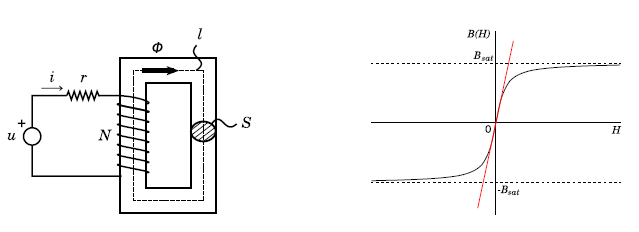


clear all; clc;
syms r i H B fi S N l K1 K2 u L

% Flux linkage -lambda-
% Resistance -r-
% Voltage -u- 
% Current -i- 
% Excitation -H- 
% Magnetic flux density -B- 
% Flux -fi-
% Section S
% Turns N

%Magnetic flux
lambda= N*S*K1*atan(K2*N*i/l)

$$lambda = K_{1}\,N\,S\,\mathrm{atan}\left(\frac{K_{2}\,N\,i}{l}\right)$$

%Flux mag derivative
dlambda=diff(lambda,i)

$$dlambda = \frac{K_{1}\,K_{2}\,N^{2}\,S}{l\,\left(\frac{{K_{2}}^{2}\,N^{2}\,i^{2}}{l^{2}}+1\right)}$$

pretty (dlambda)

            2
     K1 K2 N  S
-------------------
  /   2  2  2     \
  | K2  N  i      |
l | --------- + 1 |
  |      2        |
  \     l         /




% Nonlinear equation: u=r*i+d/dt(lambda)
x= inv(dlambda)*u-inv(dlambda)*r*i

$$x = \frac{l\,u\,\left(\frac{{K_{2}}^{2}\,N^{2}\,i^{2}}{l^{2}}+1\right)}{K_{1}\,K_{2}\,N^{2}\,S}-\frac{i\,l\,r\,\left(\frac{{K_{2}}^{2}\,N^{2}\,i^{2}}{l^{2}}+1\right)}{K_{1}\,K_{2}\,N^{2}\,S}$$

pretty(x)

    /   2  2  2     \         /   2  2  2     \
    | K2  N  i      |         | K2  N  i      |
l u | --------- + 1 |   i l r | --------- + 1 |
    |      2        |         |      2        |
    \     l         /         \     l         /
--------------------- - -----------------------
             2                        2
      K1 K2 N  S               K1 K2 N  S




% Linear equation: u=r*i+d/dt(lambda)
Llineal=taylor(x,[i],0,'Order',2)

$$Llineal = \frac{l\,u}{K_{1}\,K_{2}\,N^{2}\,S}-\frac{i\,l\,r}{K_{1}\,K_{2}\,N^{2}\,S}$$

pretty(Llineal)

    l u         i l r
---------- - ----------
       2            2
K1 K2 N  S   K1 K2 N  S

